# **RT-QIBC analysis**

**YFP1: Cdt1**

**YFP2: Geminin**

**YFP5: Cyclin A**

**FarRed1: EdU**

**POI(:,3): CRL4Cdt2 activation time**

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
            'Cterm NR67',2:3,7:11,1:4,[0 0 0]; %1    
        'CA NR48',2:3,2:6,1:4,[0 0 0]; %1      
};


load([dataDir filesep 'C217_data.mat'],'S');
% S = loadData(conditions, dataDir);
framesPerHr = 60/8;
frameDrugAdded = 0;
frameEdU = 0;
timeStart = 3.5;
folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};


**Check stains**

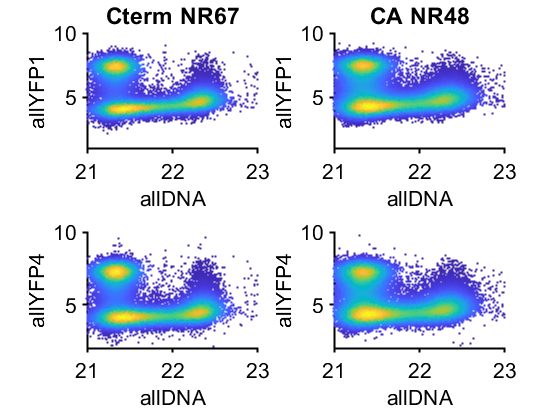

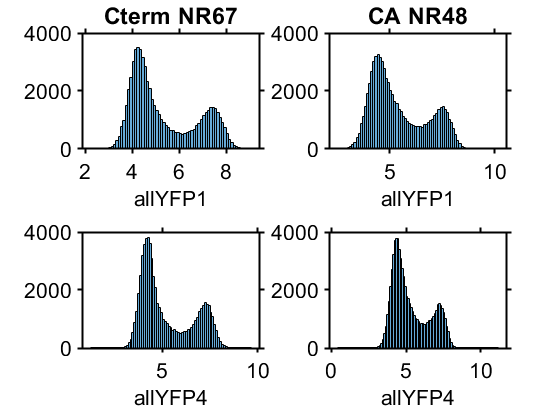

conds=[1 2];

xval = 'allDNA';
yval = 'allYFP1';
zval = 'allYFP4';

f1 = figure;
f2 = figure;
for i = 1:length(conds)
    condition = conds(i);
    xdata = log2(S(condition).(xval));
    ydata =  real(log2(S(condition).(yval)));
    zdata = real(log2(S(condition).(zval)));
    
    figure(f1)
    subplot(2,length(conds),i)
    dscatter(xdata,ydata);
    xlim([21 23])
    ylim([1 10]);
    ylabel(yval);
    xlabel(xval);
    title(conditions{condition,1});

    figure(f1)
    subplot(2,length(conds),i+length(conds))
    dscatter(xdata,zdata);
    xlim([21 23])
    ylim([2 10]);
    ylabel(zval);xlabel(xval);
    
    figure(f2)
    subplot(2,length(conds),i)
    histogram(ydata)
    xlabel(yval)
    title(conditions{condition,1});

    figure(f2)
    subplot(2,length(conds),i+length(conds))
    histogram(zdata)
    xlabel(zval)
end

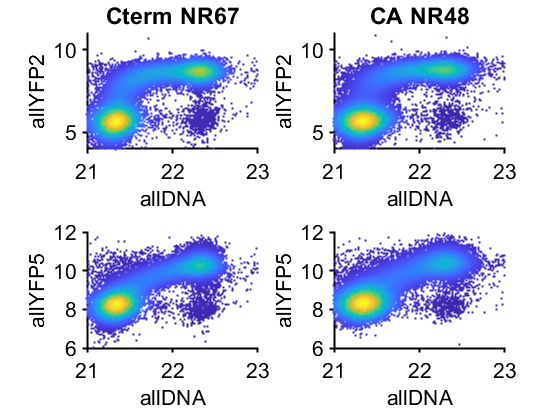

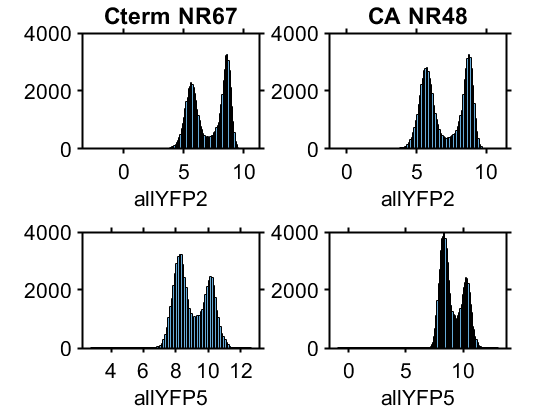


xval = 'allDNA';
yval = 'allYFP2';
zval = 'allYFP5';

f1 = figure;
f2 = figure;
for i = 1:length(conds)
    condition = conds(i);
    xdata = log2(S(condition).(xval));
    ydata =  real(log2(S(condition).(yval)));
    zdata =  real(log2(S(condition).(zval)));
    %ydata = ((pCal(2)*S(condition).YFP2(:)+pCal(1))/2/2^7.44);
    %zdata =((pCal2(2)*S(condition).YFP2(:)+pCal2(1))/2/(2^7.44 /1.8));
    
    figure(f1)
    subplot(2,length(conds),i)
    dscatter(xdata,ydata);
    xlim([21 23])
    ylim([4 11]);
    ylabel(yval);
    xlabel(xval);
    title(conditions{condition,1});

    figure(f1)
    subplot(2,length(conds),i+length(conds))
    dscatter(xdata,zdata);
    xlim([21 23])
    ylim([6 12]);
    ylabel(zval);xlabel(xval);
    
    figure(f2)
    subplot(2,length(conds),i)
    histogram(ydata)
    xlabel(yval)
    title(conditions{condition,1});

    figure(f2)
    subplot(2,length(conds),i+length(conds))
    histogram(zdata)
    xlabel(zval)
end

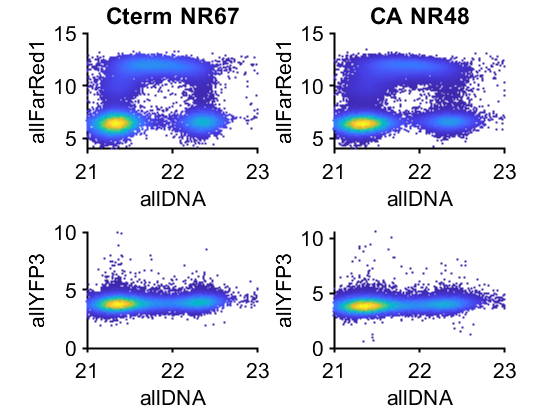

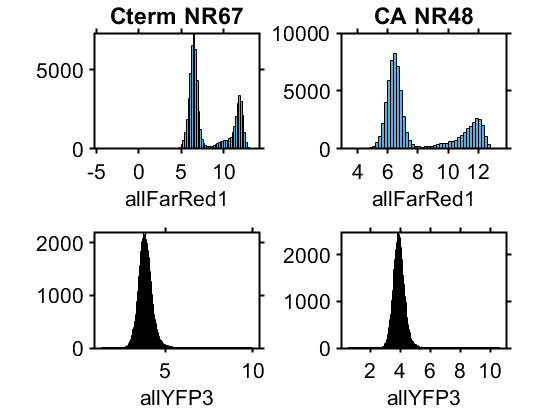


xval = 'allDNA';
yval = 'allFarRed1';
zval = 'allYFP3';

f1 = figure;
f2 = figure;
for i = 1:length(conds)
    condition = conds(i);
    xdata = log2(S(condition).(xval));
    ydata =  real(log2(S(condition).(yval)));
    zdata =  real(log2(S(condition).(zval)));
    %ydata = ((pCal(2)*S(condition).YFP2(:)+pCal(1))/2/2^7.44);
    %zdata =((pCal2(2)*S(condition).YFP2(:)+pCal2(1))/2/(2^7.44 /1.8));
    
    figure(f1)
    subplot(2,length(conds),i)
    dscatter(xdata,ydata);
    xlim([21 23])
    ylim([4 15]);
    ylabel(yval);
    xlabel(xval);
    title(conditions{condition,1});

    figure(f1)
    subplot(2,length(conds),i+length(conds))
    dscatter(xdata,zdata);
    xlim([21 23])
    %ylim([6 12]);
    ylabel(zval);xlabel(xval);
    
    figure(f2)
    subplot(2,length(conds),i)
    histogram(ydata)
    xlabel(yval)
    title(conditions{condition,1});

    figure(f2)
    subplot(2,length(conds),i+length(conds))
    histogram(zdata)
    xlabel(zval)
end

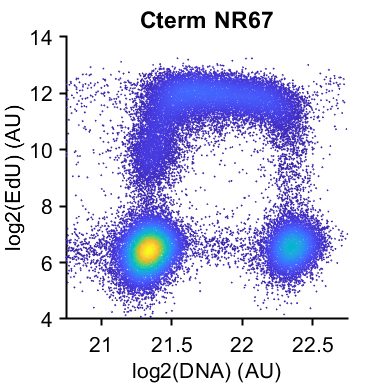

conds=[1];

xval = 'allDNA';
yval = 'allFarRed1';

for i = 1:length(conds)
    condition = conds(i);
    xdata = log2(S(condition).(xval));
    ydata =  (log2(S(condition).(yval)));
    inds = xdata > 20.75 & xdata < 22.75 & ydata > 2;
    xdata = xdata(inds);
    ydata = ydata(inds);
    
    figure('Units', 'Inches', 'Position', [0, 0, 4, 4]), hold on
    dscatter(xdata,ydata,'MSIZE',3,'MARKER','o');
    xlim([21 23]-.25)
    ylim([4 14]);
    ylabel('log2(EdU) (AU)');
    xlabel('log2(DNA) (AU)');
    title(conditions{condition,1});
    axis square
            print_pdf([pwd() '\Figs\dnavsedu.pdf'])

end

**Set thresholds**

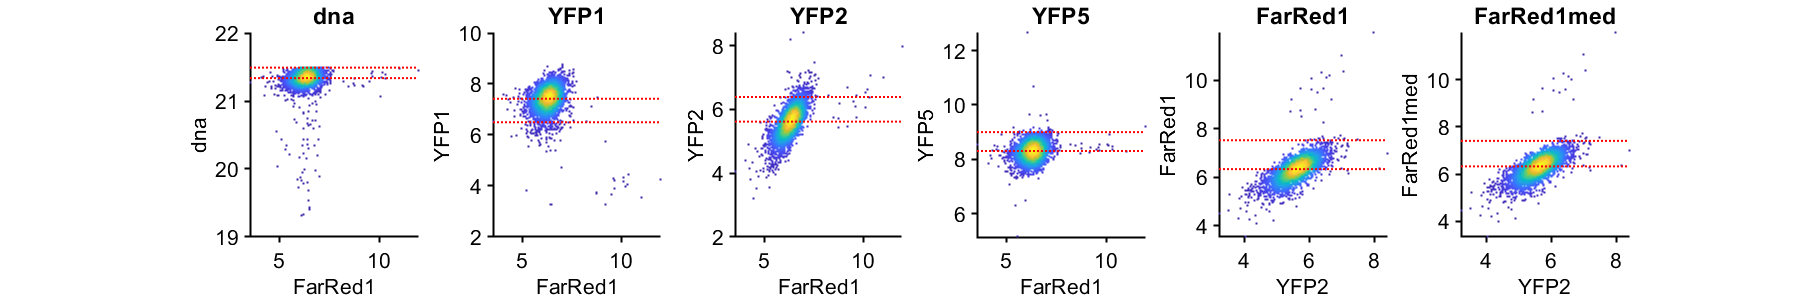


%% Set gates time after mitosis
cond=1;
gate = struct();
gates = {'dna','YFP1','YFP2','YFP5','FarRed1','FarRed1med'};
plotting = {'FarRed1','FarRed1','FarRed1','FarRed1','YFP2','YFP2'};
prctiles = {[50 99], [5 50],[50 95],[50 99],[50 99],[50 99]};

figure('pos',[0 0 length(gates)*300 300 ])

for i = 1:length(gates)
    inds = S(cond).POI_time(:,1) <= 2 & S(cond).POI_time(:,1) > 1 & S(cond).dna < 2^21.5;
    ydata = S(cond).(gates{i})(inds,:);
    xdata = S(cond).(plotting{i})(inds,:);
    
    gate.([gates{i} '_G1']) = prctile(ydata, prctiles{i});
    
    subplot(1,length(gates),i)
    dscatter(log2(xdata),log2(ydata));
    hline( log2(gate.([gates{i} '_G1'])))
    ylabel(gates{i});
    xlabel(plotting{i});
    title(gates{i});
    
    if strcmp(gates{i},'FarRed1')
        g1cellsedu = ydata;
    end
    if strcmp(gates{i},'YFP2')
        g1cellsgem = ydata;
    end
        if strcmp(gates{i},'YFP5')
        g1cellscyc = ydata;
    end
end

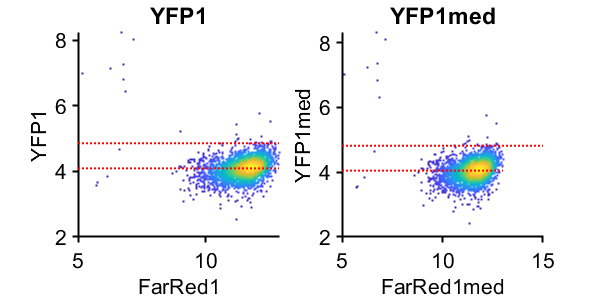



%% set S phase gates
cond=1;
gates = {'YFP1','YFP1med'};
plotting = {'FarRed1','FarRed1med'};
prctiles = {[50 99],[50 99]};

figure('pos',[0 0 length(gates)*300 300 ])

for i = 1:length(gates)
    inds = S(cond).POI_time(:,3) <= 2 &  S(cond).POI_time(:,3) > 1 ;
    ydata = S(cond).(gates{i})(inds,:);
    xdata = S(cond).(plotting{i})(inds,:);
    
    gate.([gates{i} '_S']) = prctile(ydata, prctiles{i});
    
    subplot(1,length(gates),i)
    dscatter(log2(xdata),log2(ydata));
    hline( log2(gate.([gates{i} '_S'])))
    
    ylabel(gates{i});
    xlabel(plotting{i});
    title(gates{i});
    
end

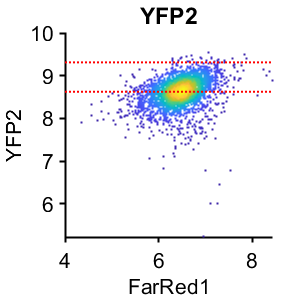


%% set G2 phase gates
cond=1;
gates = {'YFP2'};
plotting = {'FarRed1'};
prctiles = {[50 99]};

figure('pos',[0 0 length(gates)*300 300 ])

for i = 1:length(gates)
    inds = S(cond).POI_time(:,5) > 0 & S(cond).FarRed1 < 2*gate.FarRed1_G1(2) & S(cond).POI_time(:,3) < 10 ...
        & S(cond).YFP5 > 2^9.75;
    ydata = S(cond).(gates{i})(inds,:);
    xdata = S(cond).(plotting{i})(inds,:);
    
    gate.([gates{i} '_G2']) = prctile(ydata, prctiles{i});
    
    subplot(1,length(gates),i)
    dscatter(log2(xdata),log2(ydata));
    hline( log2(gate.([gates{i} '_G2'])))
    
    ylabel(gates{i});
    xlabel(plotting{i});
    title(gates{i});
    
    if strcmp(gates{i},'YFP2')
        g2cellsgem = ydata;
    end

end

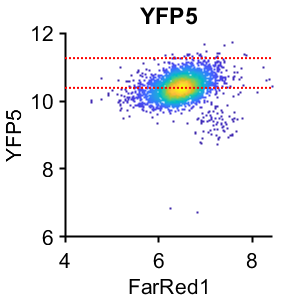


%% set G2 phase gates
cond=1;
gates = {'YFP5'};
plotting = {'FarRed1'};
prctiles = {[50 99]};

figure('pos',[0 0 length(gates)*300 300 ])

for i = 1:length(gates)
    inds = S(cond).POI_time(:,5) > 0 & S(cond).FarRed1 < 2*gate.FarRed1_G1(2) & S(cond).POI_time(:,3) < 10 ...
        & S(cond).YFP2 > 2^8;
    ydata = S(cond).(gates{i})(inds,:);
    xdata = S(cond).(plotting{i})(inds,:);
    
    gate.([gates{i} '_G2']) = prctile(ydata, prctiles{i});
    
    subplot(1,length(gates),i)
    dscatter(log2(xdata),log2(ydata));
    hline( log2(gate.([gates{i} '_G2'])))
    
    ylabel(gates{i});
    xlabel(plotting{i});
    title(gates{i});

   if strcmp(gates{i},'YFP5')
        g2cellscyc = ydata;
    end
end

**Check GMNN vs EdU levels all cells**

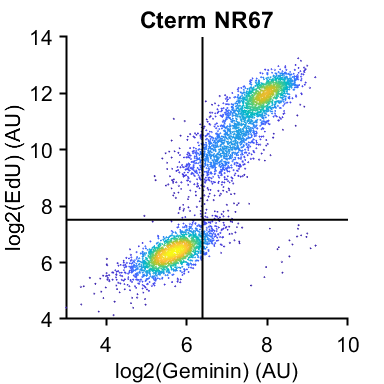

total = 5178

Scells = 236

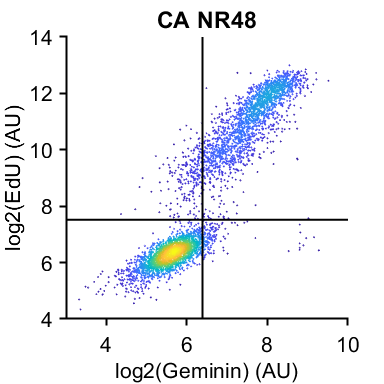

conds=[1 2];

xval = 'YFP2';
yval = 'FarRed1';

for i = 1:length(conds)
    condition = conds(i);
    xdata = (log2(S(condition).(xval)));
    ydata =  (log2(S(condition).(yval)));
    %
    % inds = S(condition).dna < 2^21.5;
    inds = S(condition).POI_time(:,1) > 3 & S(condition).POI_time(:,1) < 5;
    xdata = xdata(inds);
    ydata = ydata(inds);
    
    figure('Units', 'Inches', 'Position', [0, 0, 4, 4]), hold on
    dscatter(xdata,ydata,'MSIZE',3,'MARKER','o');
    xlim([3 10])
    ylim([4 14])
    vline(log2(gate.YFP2_G1(2)),'k');
    hline(log2(gate.FarRed1_G1(2)),'k');
    axis square
    ylabel('log2(EdU) (AU)');
    xlabel('log2(Geminin) (AU)');
    title(conditions{condition,1});%h = vline(20.5,'k');v = hline(9,'k');
    
    if condition == 1
        print_pdf([pwd() '\Figs\GMNNvsEdU.pdf'])
        total = length(xdata)
        Scells = sum(xdata<log2(gate.YFP2_G1(2)) & ydata>log2(gate.FarRed1_G1(2)))

    end
end

**Check GMNN vs EdU levels all cells**

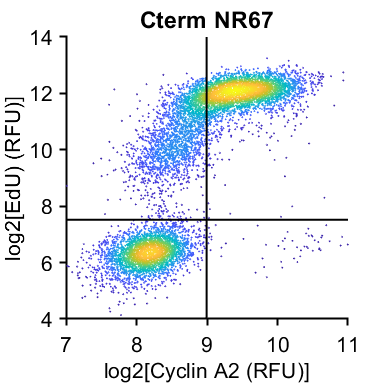

total = 9365

Scells = 2415

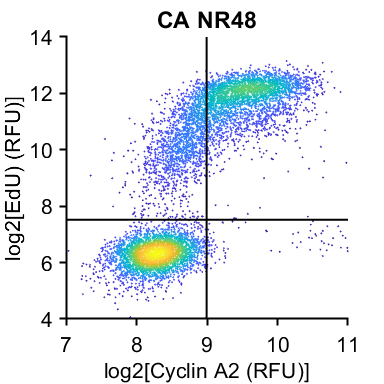

conds=[1 2];

xval = 'YFP5';
yval = 'FarRed1';

for i = 1:length(conds)
    condition = conds(i);
    xdata = (log2(S(condition).(xval)));
    ydata =  (log2(S(condition).(yval)));
    %
    % inds = S(condition).dna < 2^21.5;
    inds = S(condition).POI_time(:,1) > 3 & S(condition).POI_time(:,1) < 7;
    xdata = xdata(inds);
    ydata = ydata(inds);
    
    figure('Units', 'Inches', 'Position', [0, 0, 4, 4]), hold on
    dscatter(xdata,ydata,'MSIZE',3,'MARKER','o');
    xlim([7 11])
    ylim([4 14])
    vline(log2(gate.YFP5_G1(2)),'k');
    hline(log2(gate.FarRed1_G1(2)),'k');
    axis square
    ylabel('log2[EdU) (RFU)]');
    xlabel('log2[Cyclin A2 (RFU)]');
    title(conditions{condition,1});%h = vline(20.5,'k');v = hline(9,'k');
    
    if condition == 1
        print_pdf([pwd() '\Figs\cycavsEdU.pdf'])
        total = length(xdata)
        Scells = sum(xdata<log2(gate.YFP5_G1(2)) & ydata>log2(gate.FarRed1_G1(2)))

    end
end

**Time since CRL IF levels for export**

cond=1;
poiAligned=3;
offset=0;


rng(1)
gateVals = {{}};
rangeVals = {{[]}};

xrange = [0 8];

ind= ~isnan(S(cond).POI_time(:,poiAligned(1))) & ...
    gate_vals(S(cond), gateVals{1}, rangeVals{1})  & S(cond).POI_time(:,poiAligned(1)) <=8;

xdata = S(cond).POI_time(ind,poiAligned);
ydata = [];
ydata(:, 1) = (S(cond).YFP5(ind) - gate.YFP5_G1(1))/(1337 - gate.YFP5_G1(1));
ydata(:, 2) = (S(cond).YFP2(ind) - gate.YFP2_G1(1))/(gate.YFP2_G2(1)- gate.YFP2_G1(1));
ydata(:, 3) = log2(S(cond).FarRed1(ind)) ;

length(xdata)

ans = 13262

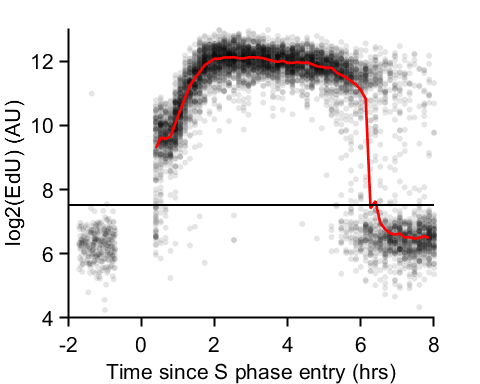

edges = unique(xdata);
[binData, edges] = bin_xy(xdata, ydata, {'mean','median'},...
    'Edges',edges);
midpoints = edges;
midpoints = midpoints(1:end-1);


f1 = figure('Units', 'Inches', 'Position', [0, 0, 5, 4]);
hold on
subG1 = randsample(log2(g1cellsedu),300);
subs_cells = randsample(size(ydata,1),6000);
subs = false(size(ydata,1),1);
subs(subs_cells) = true;
subs = subs & ydata(:,2) < 2 & ydata(:,2) > -.1;
fakexg1 = rand(size(subG1)) - 1.7;
%dscatter(xdata,ydata2);
scatter(xdata(subs),ydata(subs,3),20,'k','filled','MarkerFaceAlpha',.1)
scatter(fakexg1,subG1 ,20,'k','filled','MarkerFaceAlpha',.1)
plot(midpoints,binData(3).median,'r','LineWidth',2);
ylim([4 13]);
xlim([-2 8]);
ylabel('log2(EdU) (AU)');xlabel({'Time since S phase entry (hrs)'});
%title(conditions{conds(i),1});
h=hline(log2(gate.FarRed1_G1(2)),'k');
hold off
print_pdf([pwd() '\Figs\EdU_timesinceS.pdf'])

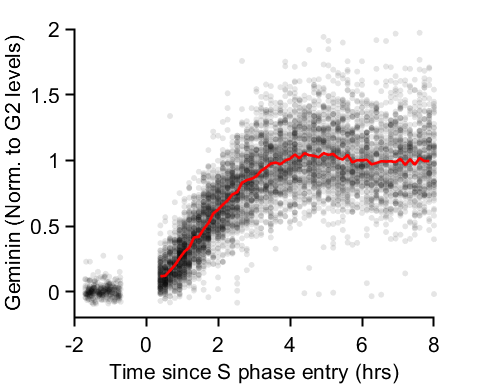



f2 = figure('Units', 'Inches', 'Position', [0, 0, 5, 4]);
hold on
%dscatter(xdata,ydata3);
subG1 = (randsample(g1cellsgem,300) - gate.YFP2_G1(1)) /(gate.YFP2_G2(1)- gate.YFP2_G1(1));
% subG2 = randsample(g2cellsgem,400)/gate.YFP2_G2(1);
fakexg1 = rand(size(subG1)) - 1.7;
% fakexg2 = rand(size(subG2)) + 9;
scatter(xdata(subs),ydata(subs,2) ,20,'k','filled','MarkerFaceAlpha',.1)
scatter(fakexg1,subG1 ,20,'k','filled','MarkerFaceAlpha',.1)
% scatter(fakexg2,subG2 ,20,'k','filled','MarkerFaceAlpha',.1)
plot(midpoints,binData(2).median,'r','LineWidth',2);
ylim([-.2 2]);
xlim([-2 8]);
ylabel('Geminin (Norm. to G2 levels)');xlabel({'Time since S phase entry (hrs)'});
%title(conditions{conds(i),1});
% h=hline(gate.YFP2_G1(2),'k--');

hold off
print_pdf([pwd() '\Figs\GMNN_timesinceS.pdf'])

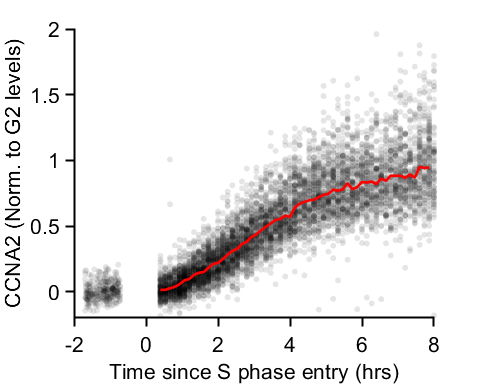



f3 = figure('Units', 'Inches', 'Position', [0, 0, 5, 4]);
hold on
%dscatter(xdata,ydata3);
subG1 = (randsample(g1cellscyc,300)- gate.YFP5_G1(1))/(gate.YFP5_G2(1) - gate.YFP5_G1(1));
% subG2 = randsample(g2cellsgem,400)/gate.YFP2_G2(1);
fakexg1 = rand(size(subG1)) - 1.7;
% fakexg2 = rand(size(subG2)) + 9;
subs = false(size(ydata,1),1);
subs(subs_cells) = true;
subs = subs & ydata(:,1) < 2 & ydata(:,1) > -.2;

scatter(xdata(subs),ydata(subs,1) ,20,'k','filled','MarkerFaceAlpha',.1)
scatter(fakexg1,subG1 ,20,'k','filled','MarkerFaceAlpha',.1)
% scatter(fakexg2,subG2 ,20,'k','filled','MarkerFaceAlpha',.1)
plot(midpoints,binData(1).median,'r','LineWidth',2);
ylim([-.2 2]);
xlim([-2 8]);
ylabel('CCNA2 (Norm. to G2 levels)');xlabel({'Time since S phase entry (hrs)'});
%title(conditions{conds(i),1});
% h=hline(gate.YFP2_G1(2),'k--');
hold off
print_pdf([pwd() '\Figs\CCNA2_timesinceS.pdf'])

**stat test gem comparison **

Gate for early mitosis, first .3 hrs, high/low geminin

rng(5)
yval = 'YFP2';

f1 = figure;
test = {};
ally = [];
group = [];

%%% G1 levels
condition = 1;
ydata = g1cellsgem;
inds = randsample(length(ydata),500);
ydata = ydata(inds);

% ydata(ydata<0) = [];
test{1} = ydata;
ally = [ally; ydata];
group = [group; repmat(1,size(ydata))];

%%% early S phase cells
condition =  1;
ydata = S(condition).(yval);

inds = S(condition).POI_time(:,3) <= 4*8/60 & S(condition).dna < 2^21.5 ;
ydata = ydata(inds);

% ydata(ydata<0) = [];
test{2} = ydata;
ally = [ally; ydata];
group = [group; repmat(2,size(ydata))];


%%% G2 levels
condition = 1;
ydata = g2cellsgem;

% inds = randsample(length(ydata),700);
% ydata = ydata(inds);

test{3} = ydata;
ally = [ally; ydata];
group = [group; repmat(3,size(ydata))];



% ally = ally - median(ally(group ==1));
ally = (ally - median(ally(group == 1)))/(median(ally(group == 3))- median(ally(group == 1)));
test = cellfun(@(x) (x - median(test{1}))/(median(test{3})- median(test{1})),test,'UniformOutput',false);
cellfun(@median,test)

ans =          0    0.1169    1.0000


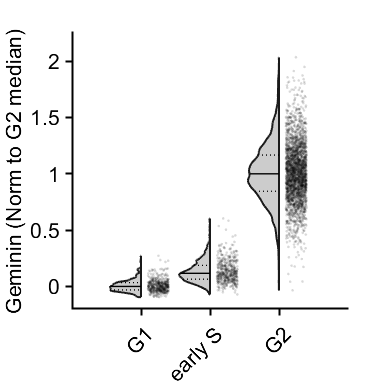


figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1],...
    'xNames',{'G1','early S','G2'});
set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',1.5)
hold on
jit = 0.3*rand(size(group)) + .1;
scatter(group+jit, (ally), 4,'k','filled','MarkerFaceAlpha',.15);
ylabel('Geminin (Norm to G2 median)')
ylim([-.2 2.25])
xtickangle(45)
pbaspect([1 1 1])
print_pdf([pwd() '\Figs\gmnn_compare_scatter.pdf'])

**stat test ccn comparison **

Gate for early mitosis, first .3 hrs, high/low geminin

rng(2)
yval = 'YFP5';

f1 = figure;
test = {};
ally = [];
group = [];

%%% G1 levels
condition = 1;
ydata = g1cellscyc;
inds = randsample(length(ydata),700);
ydata = ydata(inds);

% ydata(ydata<0) = [];
test{1} = ydata;
ally = [ally; ydata];
group = [group; repmat(1,size(ydata))];

%%% early S phase cells
condition =  1;
ydata = S(condition).(yval);

inds = S(condition).POI_time(:,3) <= 4*8/60 & S(condition).dna < 2^21.5 ;
ydata = ydata(inds);

% ydata(ydata<0) = [];
test{2} = ydata;
ally = [ally; ydata];
group = [group; repmat(2,size(ydata))];


%%% G2 levels
condition = 1;
ydata = g2cellscyc;

% inds = randsample(length(ydata),700);
% ydata = ydata(inds);

test{3} = ydata;
ally = [ally; ydata];
group = [group; repmat(3,size(ydata))];



% ally = ally - median(ally(group ==1));
ally = (ally - median(ally(group == 1)))/(median(ally(group == 3))- median(ally(group == 1)));
inds = ally > -.2 & ally < 2.5;
group = group(inds);
ally = ally(inds);

test = cellfun(@(x) (x - median(test{1}))/(median(test{3})- median(test{1})),test,'UniformOutput',false);
test = cellfun(@(x) x(x > -.2 & x < 2.5),test,'UniformOutput',false)

test = 1×3 cell array
    {699×1 double}    {503×1 double}    {2637×1 double}


cellfun(@median,test)

ans =     0.0000    0.0123    0.9996


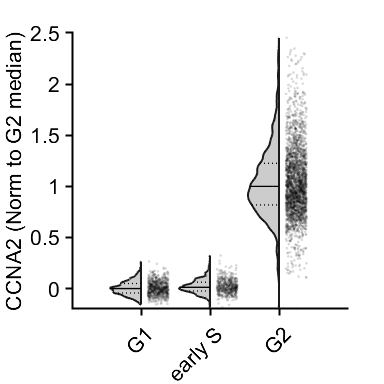


figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1],...
    'xNames',{'G1','early S','G2'});
set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',1.5)
hold on
jit = 0.3*rand(size(group)) + .1;
scatter(group+jit, (ally), 4,'k','filled','MarkerFaceAlpha',.15);
ylabel('CCNA2 (Norm to G2 median)')
ylim([-.2 2.5])
xtickangle(45)
pbaspect([1 1 1])
print_pdf([pwd() '\Figs\ccna_compare_scatter.pdf'])




[h,p,ci,stats] = ttest(test{2})

h = 1

p = 1.2186e-11

ci =     0.0151
    0.0271


stats = struct with fields:
    tstat: 6.9397
       df: 502
       sd: 0.0682
